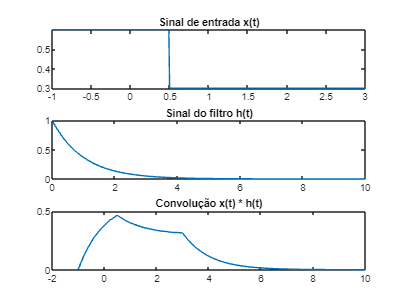

% Definindo o sinal de entrada x(t)
t_x = -1:0.01:3;
x = zeros(size(t_x));
x(t_x >= -1 & t_x <= 0.5) = 0.6;
x(t_x >= 0.5 & t_x <= 3) = 0.3;

% Definindo o sinal do filtro h(t)
t_h = 0:0.01:10;
h = exp(-t_h);

% Calculando a convolução
t_conv = -1:0.1:10;
convol = zeros(size(t_conv));
for i = 1:length(t_conv)
    t = t_conv(i);
    convol(i) = sum(x .* (exp(-(t-t_x)) .* heaviside(t-t_x)) * 0.01);
end

% Plotando os sinais e a convolução
subplot(3,1,1);
plot(t_x, x);
title('Sinal de entrada x(t)');

subplot(3,1,2);
plot(t_h, h);
title('Sinal do filtro h(t)');
ys1 = cat(2, [0 0], convol);
subplot(3,1,3);

plot(t_conv, ys1);

Error using plot
Vectors must be the same length.

title('Convolução x(t) * h(t)');

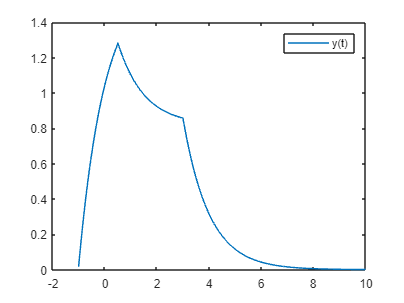

% Definição dos sinais x(t) e h(t)
t = -1:0.01:10;
x = 0.6*(t>=-1 & t<=0.5) + 0.3*(t>=0.5 & t<=3);
h = exp(-t);

% Cálculo da convolução
y = zeros(size(t)); % Inicializa o vetor de saída
for i = 1:length(t)
    for j = 1:i
        y(i) = y(i) + x(j)*h(i-j+1)*(t(2)-t(1)); % Somatório de produtos de amostras
    end
end

% Plot dos sinais e do resultado da convolução
plot(t, y);
legend('y(t)');

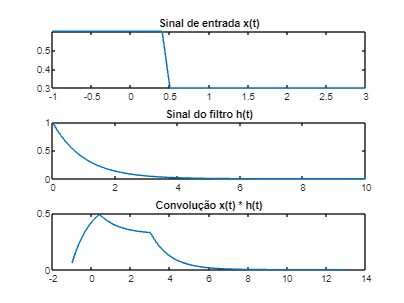

% Definindo o sinal de entrada x(t)
t_x = -1:0.1:3;
x = zeros(size(t_x));
x(t_x >= -1 & t_x <= 0.5) = 0.6;
x(t_x >= 0.5 & t_x <= 3) = 0.3;

% Definindo o sinal do filtro h(t)
t_h = 0:0.1:10;
h = exp(-t_h);

% Calculando a convolução
y = conv(x, h)*0.1;
t_y = (0:(length(y)-1))*0.1-1;

% Plotando os sinais e a convolução
subplot(3,1,1);
plot(t_x, x);
title('Sinal de entrada x(t)');

subplot(3,1,2);
plot(t_h, h);
title('Sinal do filtro h(t)');

subplot(3,1,3);
plot(t_y, y);
title('Convolução x(t) * h(t)');